# Breathing extracted from cardiac signals

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

We acknowledge using RRest toolbox provided by P. Charlton [1].

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter9/RespRatefromECG'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

In this notebook we first generate artificial ECG and PPG signals. Their freqeuncy is 60 beat per minute. Then we add different modulations and noise. Breathing is simulated as a sinewave signal. Signals are generated based on [1].

Please note that only ECG signal is used for further processing. The same analysis can be done with the PPG signal too.

These steps were followed in order to determine the breathing rate:

- Detecting fiducial points on the cardiac signal of interest (ECG or PPG)

- Extracting the breathing signal

- Estimating breathing rate

Of course, it is possible to extract the breathing signal automatically, for example by using Wavelet transform, without determining the fiducial points on the ECG signal.

### Generating signals

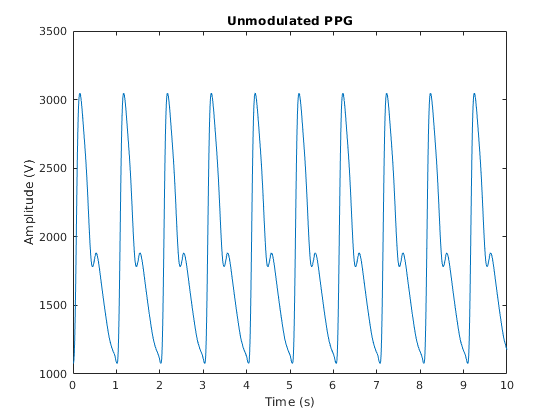

fs=100;
%N=10000;
br_rate=0.15; %in Hz
br_rate_bpm=br_rate*60;
fm=0.05;
bm=0.1;
am=0.1;
% EPG beat data
ecg_data.beat.t = 0:0.01:1;
ecg_data.beat.v = [-0.120000000000000,-0.120000000000000,-0.125000000000000,-0.122500113257034,-0.125000000000000,-0.120000000000000,-0.125000000000000,-0.117500065569862,-0.125000000000000,-0.117499958278698,-0.120000000000000,-0.120000000000000,-0.124999856955537,-0.122500005960186,-0.105000131124091,-0.115000000000000,-0.110000000000000,-0.122499946358326,-0.125000000000000,-0.109999558946239,-0.100000357611158,-0.0899996065808297,-0.0750000000000000,-0.0775001728453928,-0.0850000000000000,-0.0975001490224131,-0.100000000000000,-0.0925001251639052,-0.0949997377518178,-0.0824998986647591,-0.0800000000000000,-0.0800000000000000,-0.100000429133389,-0.0299993562231754,0.464997210632973,0.997500745023246,0.954992990821313,0.134999821173104,-0.194999845035165,-0.165000035761116,-0.119999880796281,-0.117499958273724,-0.110000202646322,-0.107499934437955,-0.109999928477768,-0.100000000000000,-0.100000000000000,-0.0900000000000000,-0.0949999761592562,-0.0824998390749790,-0.0800000000000000,-0.0675001609250210,-0.0649999761592562,-0.0574998867564668,-0.0500000000000000,-0.0400000000000000,-0.0300000000000000,-0.0124999344379545,0.00500020264632248,0.0275000417262755,0.0649997615925615,0.100000035761115,0.145000309929670,0.189999988078207,0.224999666229586,0.252499970199070,0.270000000000000,0.275000000000000,0.250000214566695,0.197500232447252,0.114999761592563,0.0325003040057223,-0.0299992132554528,-0.0849997496721898,-0.105000023840744,-0.130000000000000,-0.130000000000000,-0.140000000000000,-0.130000000000000,-0.127500196709585,-0.120000000000000,-0.120000000000000,-0.110000000000000,-0.110000000000000,-0.105000000000000,-0.105000000000000,-0.100000000000000,-0.100000000000000,-0.100000000000000,-0.100000000000000,-0.104999821194421,-0.110000000000000,-0.110000000000000,-0.105000000000000,-0.114999773512934,-0.120000000000000,-0.115000000000000,-0.122500113257034,-0.115000000000000,-0.120000000000000,-0.110000000000000];

% PPG beat data
ppg_data.beat.t = 0:0.01:1;
ppg_data.beat.v = [1077,1095.27676998271,1150.39696200268,1253.64011384634,1410.01430649103,1614.23738042021,1852.88862847947,2107.19963850395,2354.10827203910,2571.83504395768,2747.58603743220,2878.78047565119,2967.12445239160,3018.75510162723,3042.94721680823,3047.45001341082,3037.62026345592,3018.14128598677,2991.80738548651,2959.68011205818,2924.12507822977,2885.14270668177,2843.86782834153,2802.08903767062,2759.59973773619,2716.75011175682,2673.89981522322,2630.12661808970,2584.21488466353,2533.75439619717,2480.71246051141,2423.10076799285,2360.92007271860,2294.87110683952,2226.11520653275,2155.41275815825,2085.84032425344,2019.82560572195,1959.08788519998,1905.61966740180,1860.15018328118,1823.59858526554,1799.16523439130,1785.68124422590,1781.40496155451,1785.65000894081,1795.60758813888,1810.23123770638,1825.88000834451,1843.33369762174,1863.68739383102,1877.70370775466,1882.41001847768,1880.67124988824,1874.06744888836,1862.89381761287,1847.14991953269,1829.89768909817,1810.34993145378,1788.72101296379,1765.94996721702,1742.03613261809,1717.39751028193,1692.75877484727,1668.68005245276,1644.48098438338,1619.84239547012,1595.97728854980,1572.41003606020,1548.84233116767,1525.27517210550,1501.70741230815,1478.27021279132,1455.77367020325,1433.54980777827,1412.12496274662,1390.69993145582,1369.27500149014,1348.40755237670,1328.05378822197,1308.39978542052,1289.88870123678,1272.51984025750,1256.29379973178,1241.20988734577,1229.73332273703,1217.97235166145,1206.26252309710,1195.54992698555,1185.27003397509,1176.98743219884,1169.12989658769,1160.98994575908,1153.99245954403,1146.99245931931,1138.20624497094,1127.13495738213,1112.99225070036,1097.13740724184,1083.85480956071,1080];

ecg_data.sig.v=repmat(ecg_data.beat.v,1,100);
N=length(ecg_data.sig.v);
ecg_data.sig.t=1/fs:1/fs:N/fs;
ppg_data.sig.t=1/fs:1/fs:N/fs;
ppg_data.sig.v=repmat(ppg_data.beat.v,1,100);

T=1/fs;
figure 
plot(ppg_data.sig.t,ppg_data.sig.v);
    title('Unmodulated PPG')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
        xlim([0,10])

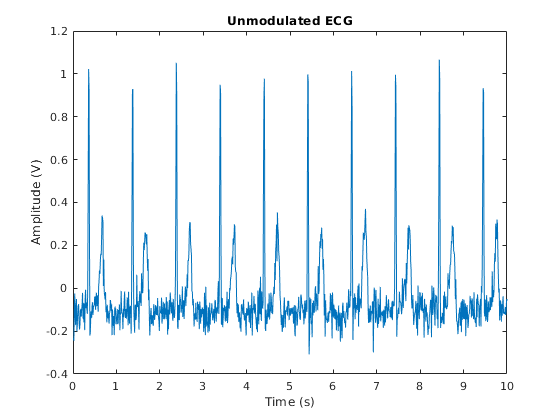

   ecg_data.sig.v=ecg_data.sig.v+0.05*randn(1,length(ecg_data.sig.v));
    figure
    plot(ecg_data.sig.t,ecg_data.sig.v);
    title('Unmodulated ECG')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
        xlim([0,10])

## Simulating breathing modulation on the ECG signal

### ECG BM

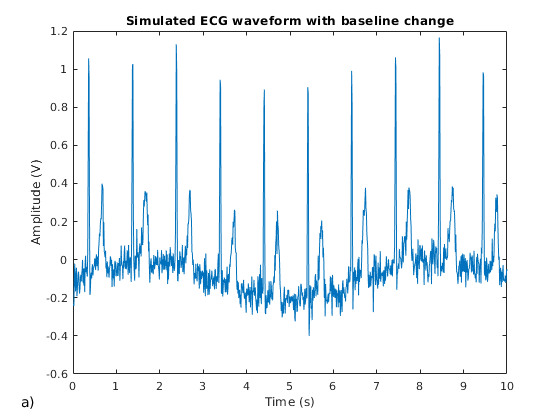

ecg_data.sig.v_bm=ecg_data.sig.v+bm*sin(2*pi*ecg_data.sig.t*br_rate);
figure
plot(ecg_data.sig.t,ecg_data.sig.v_bm)
title('Simulated ECG waveform with baseline change')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    xlim([0,10])
    annonation_save('a)',"Fig9.6a.jpg", SAVE_FLAG);

### ECG AM

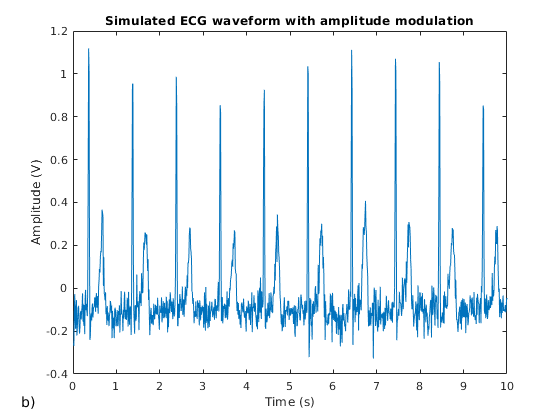

ecg_data.sig.v_am=ecg_data.sig.v.*(1+am*cos(2*pi*ecg_data.sig.t*br_rate));
figure
plot(ecg_data.sig.t,ecg_data.sig.v_am)
title('Simulated ECG waveform with amplitude modulation')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    xlim([0,10])
    annonation_save('b)',"Fig9.6b.jpg", SAVE_FLAG);

### ECG FM

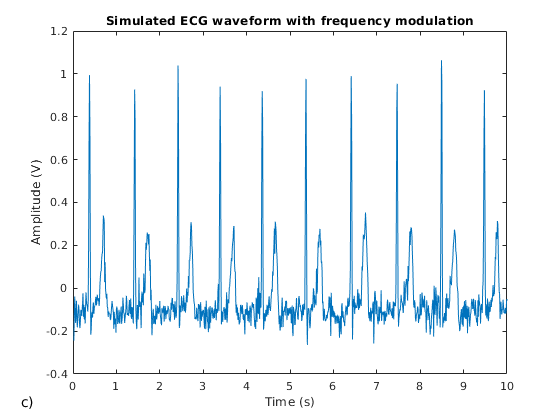

mod_time = ecg_data.sig.t + fm*sin(2*pi*br_rate*ecg_data.sig.t);
ecg_data.sig.v_fm = interp1(mod_time, ecg_data.sig.v, ecg_data.sig.t);

figure
plot(ecg_data.sig.t,ecg_data.sig.v_fm)
title('Simulated ECG waveform with frequency modulation')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    xlim([0,10])
    annonation_save('c)',"Fig9.6c.jpg", SAVE_FLAG);

### ECG all modulations 

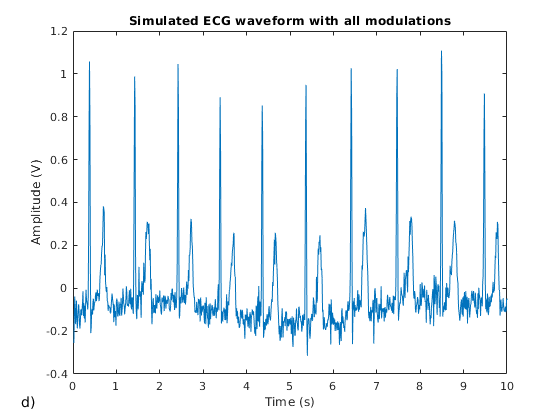

ecg_data.sig.v_all=interp1(mod_time, (ecg_data.sig.v_bm+ecg_data.sig.v_am)/2, ecg_data.sig.t);;
figure
plot(ecg_data.sig.t,ecg_data.sig.v_all)
title('Simulated ECG waveform with all modulations')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    xlim([0,10])
    annonation_save('d)',"Fig9.6d.jpg", SAVE_FLAG);

## Extracting the breathing signal

### Finding R peaks

[R1,Q,S,T,P_w, Te, ecg1] = MTEO_qrst(ecg_data.sig.v_all(2:end),fs,0);

figure,plot(ecg_data.sig.t(2:end),ecg1);
hold on,scatter(R1(:,1)/fs,R1(:,2),'r');
hold on,scatter(Q(:,1)/fs,Q(:,2),'g');
hold on,scatter(S(:,1)/fs,S(:,2),'k');
hold on,scatter(T(:,1)/fs,T(:,2),'m');
hold on,scatter(P_w(:,1)/fs,P_w(:,2),'MarkerEdgeColor',[.7 .5 0]);
ylim([-0.35,1.25])
legend({'ECG signal','R wave','Q wave','S wave','T wave', 'P wave'},'NumColumns',2)
title('Delineated ECG signal')
xlabel('Time (s)')
ylabel('Amplitude (V)')
xlim([0 10])

### Extracting Respiratory Sinus Arrhythmia (RSA) Signal

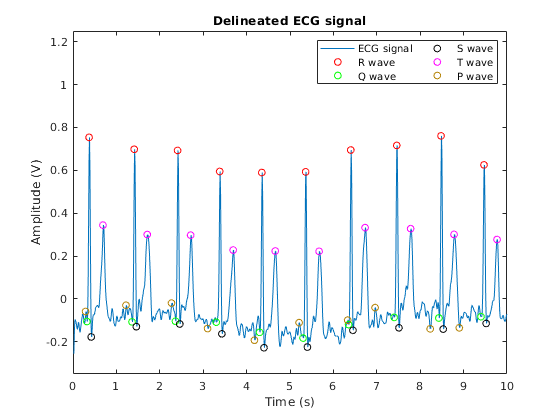

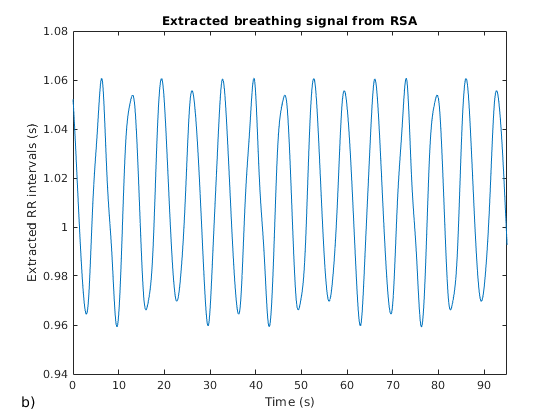

RSA  = diff(R1(:,1));
n=1:length(ecg1);
RSA_interp = interp1(R1(1:end-1,1),RSA,n, 'spline');
figure
plot(n/fs,RSA_interp/fs)
title('Extracted breathing signal from RSA')
xlabel('Time (s)')
ylabel('Extracted RR intervals (s)')
xlim([0 95])
annonation_save('b)',"Fig9.7b.jpg", SAVE_FLAG);

### Extracting Respiratory Signal based on R peak amplitude (RPA)

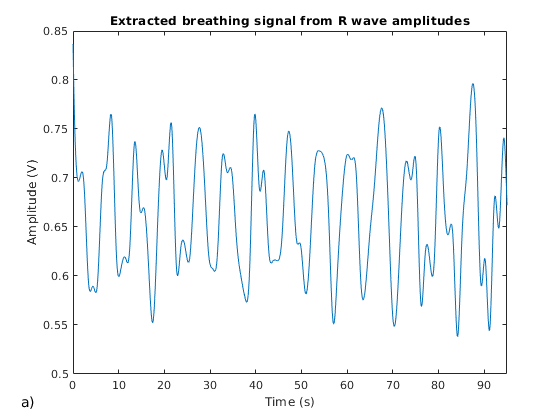


%% 
RPA_interp = interp1(R1(:,1),R1(:,2),n, 'spline');
figure
plot(n/fs,RPA_interp)
title('Extracted breathing signal from R wave amplitudes')
xlabel('Time (s)')
ylabel('Amplitude (V)')
xlim([0 95])
annonation_save('a)',"Fig9.7a.jpg", SAVE_FLAG);

## Estimating breathing rate

[breathing_rate_peaks] = br_rate_est(RSA_interp',fs)

breathing_rate_peaks = 9.0493

[breathing_rate_peaks] = br_rate_est(RPA_interp',fs)

breathing_rate_peaks = 9.1919

function [breathing_rate_peaks] = br_rate_est(sig,fs)
[m1,j1]=findpeaks(rescale1(medfilt1(sig,5)), 'MinPeakProminence',0.1,'MinPeakDistance',floor(fs/0.6), 'MinPeakWidth', floor(fs/2));
[m2,j2]=findpeaks(rescale1(-medfilt1(sig,5)), 'MinPeakProminence',0.1,'MinPeakDistance',floor(fs/0.6),  'MinPeakWidth', floor(fs/2));
%breathing_rate_peaks=60*(0.5*(legth(j1)+legth(j2)))/segment_length;
if length(j1)>1 & length(j2)>1 
     breathing_rate_peaks=2*(60*fs/(mean(diff(j1))+mean(diff(j2)))); %0.5*(length(j1)+length(j2))*60/(length(c3)/fs); 2*(60*17/(mean(diff(j1))+mean(diff(j2)))); % 0.5*(60*17/mean(diff(j1))+60*17/mean(diff(j2)));
elseif length(j1)>1
     breathing_rate_peaks=2*(60*fs/(mean(diff(j1)))) ;
elseif length(j2)>1
     breathing_rate_peaks=2*(60*fs/(mean(diff(j2)))) ;
else
     breathing_rate_peaks=0;
end
end

## References

[1] Charlton, P. H., Bonnici, T., Tarassenko, L., Clifton, D. A., Beale, R., & Watkinson, P. J. (2016). An assessment of algorithms to estimate respiratory rate from the electrocardiogram and photoplethysmogram. Physiological Measurement, 37(4), 610–626. [DOI: 10.1088/0967-3334/37/4/610](http://doi.org/10.1088/0967-3334/37/4/610)